clear;
mklist = 'o+*sd<p';
alglist = {'Origin', 'MatchSync', 'MatchLift', 'MatchALS', 'JOMGM', 'CDMGM', 'FMGM'};
cmap = lines(7);
cmap(end, :) = 0;

files = dir('./willow_*.mat');
graph_num = 3:3:15;

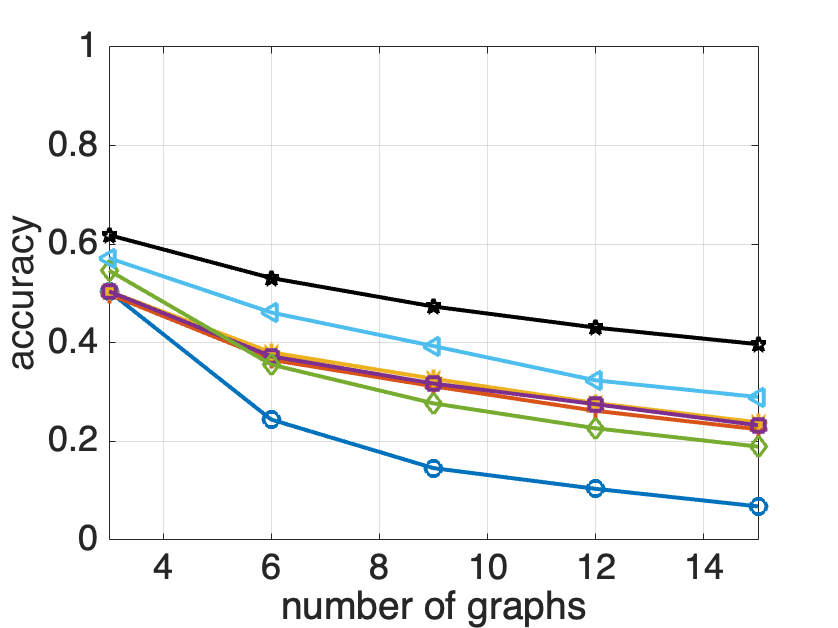

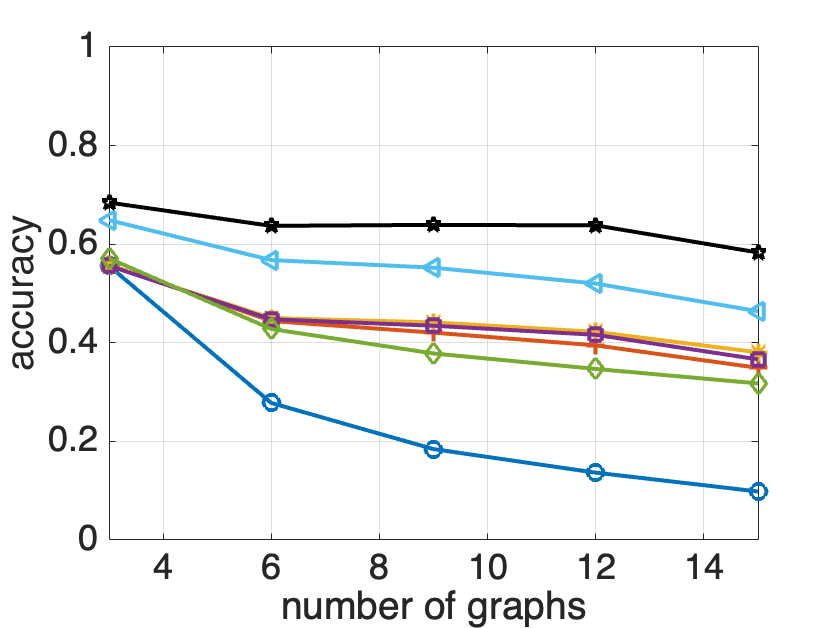

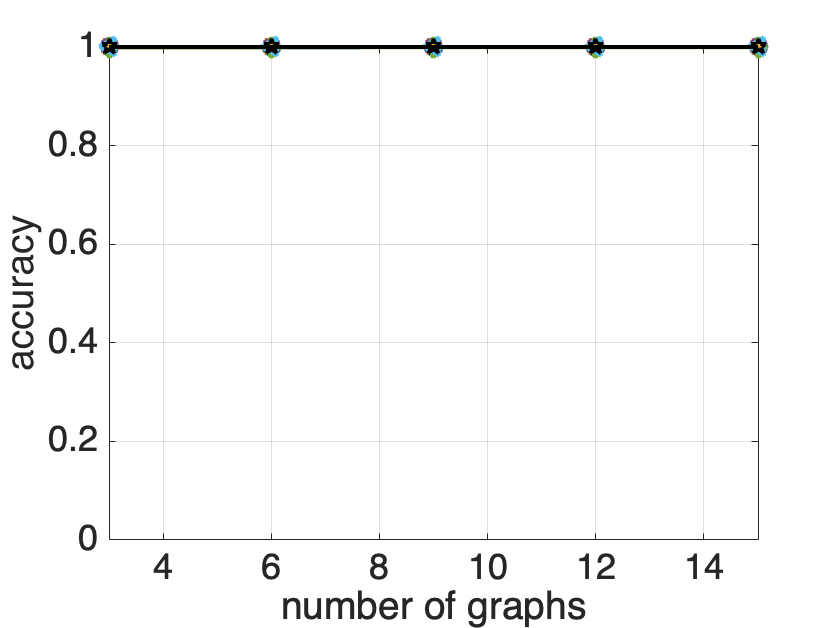

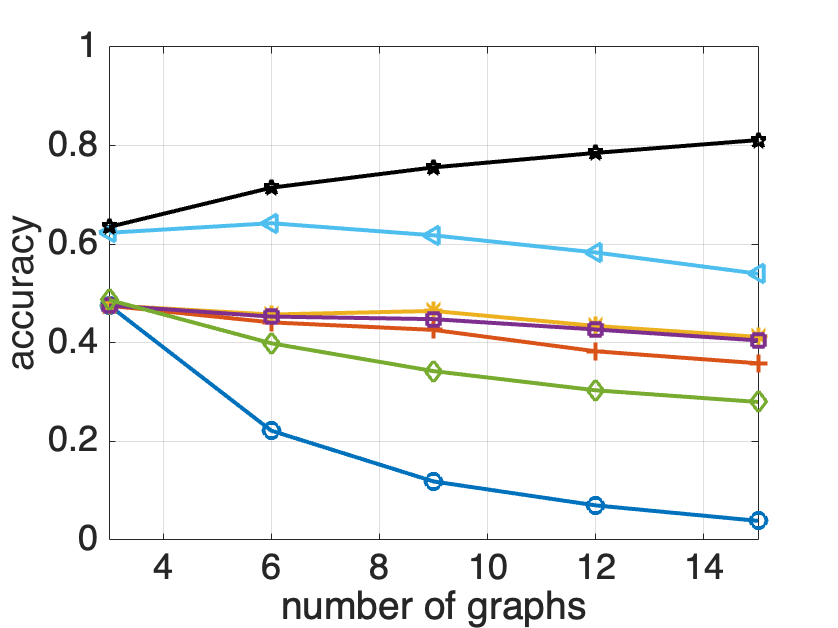

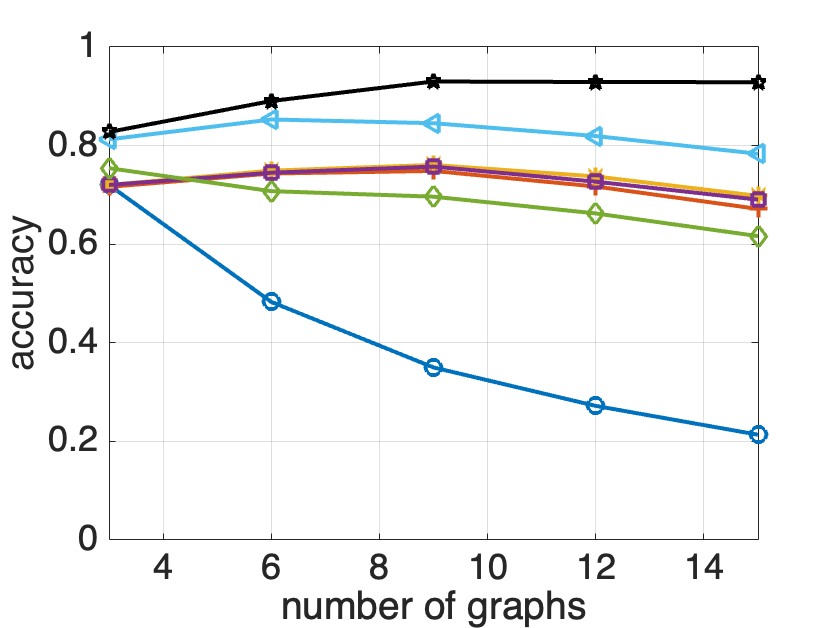

acc_all = 0;
for i = 1:length(files)
    acc = importdata([files(i).folder, filesep, files(i).name]);
    acc_all = acc_all + acc;
    figure, hold on; 
    for k = 1:length(alglist)
        plot(graph_num, acc(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
    end
    hold off;
    ylim([0, 1]);
    xlim([3, 15]);
%     legend('Location', 'best');
    xlabel('number of graphs');
    ylabel('accuracy');
    exportgraphics(gcf, ['./imgs/', 'acc_', files(i).name(1:end-4), '.pdf']);
end

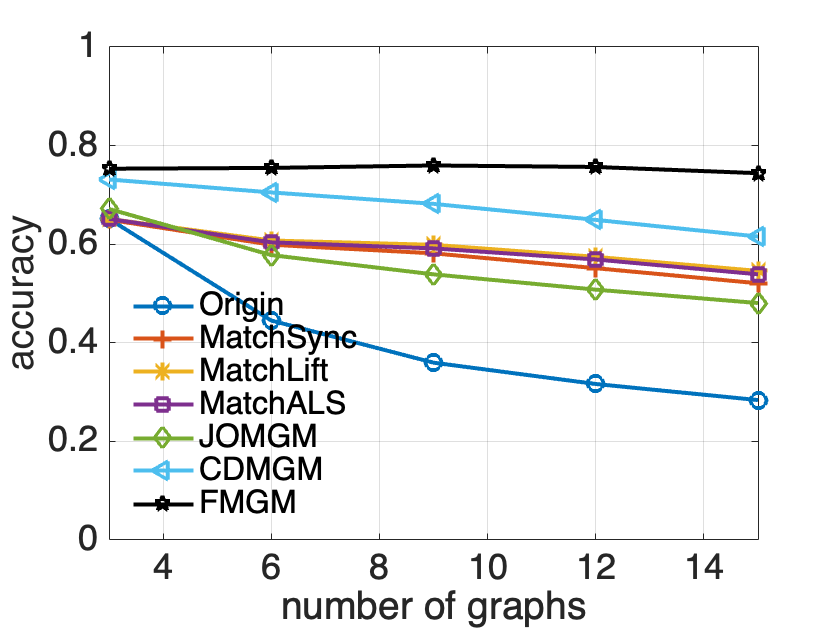

acc_all = acc_all / length(files);
figure, hold on; 
for k = 1:length(alglist)
    plot(graph_num, acc_all(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
end
hold off;
ylim([0, 1]);
xlim([3, 15]);
legend('Location', 'southwest');
xlabel('number of graphs');
ylabel('accuracy');
exportgraphics(gcf, ['./imgs/', 'acc_willow.pdf']);